addpath("Lidar\");

lidar = setupLidar("COM7")

Lidar Set

   Serial Port Object : Serial-COM7

   Communication Settings 
      Port:               COM7
      BaudRate:           115200
      Terminator:         'LF/CR'

   Communication State 
      Status:             open
      RecordStatus:       off

   Read/Write State  
      TransferStatus:     idle
      BytesAvailable:     0
      ValuesReceived:     2304
      ValuesSent:         31
 



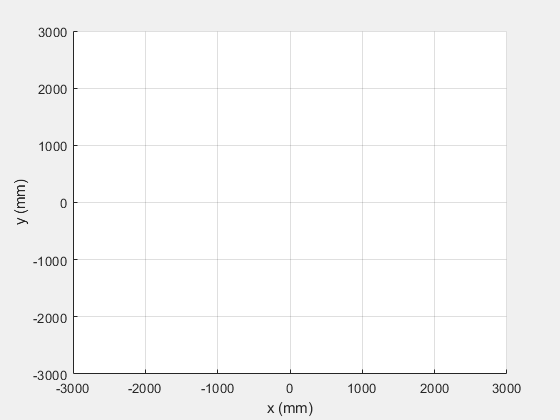

LaserPlot1.figure = figure('Name','LidarTest','NumberTitle','off', ...
    'MenuBar','figure','units','normalized','Visible','on');
LaserPlot1.axis1 = axes('Parent',LaserPlot1.figure,'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')

LaserRange = line('Parent',LaserPlot1.axis1,'XData',[],'YData',[],'LineStyle','none', ...
        'marker','.','color','b','LineWidth',2);
grid on
axis([-3000 3000 -3000 3000])
xlabel('x (mm)')
ylabel('y (mm)')

angles = (-120:240/682:120-240/682)*pi/180;
count = 0;

while count < 100
    [xData, yData] = lidarScan(lidar);
    LaserRange.XData = xData;   
    LaserRange.YData = yData;
    drawnow
    count = count +1;
    pause(0.2);
end

Invalid or deleted object.

shutdownLidar(lidar);

clear